clc
close all
clear all

m = 20 ;
k = 1000 ;

w0 = sqrt(k/m)

w0 = 7.0711

s1 = sqrt(-2+sqrt(3))*w0

s1 = 0.0000 + 3.6603i

s2 = sqrt(-2-sqrt(3))*w0

s2 = 0.0000 +13.6603i


w1 = imag(s1)

w1 = 3.6603

w2 = imag(s2)

w2 = 13.6603


r1 = ( m*(-2+sqrt(3))*w0^2 + 3*k ) / (2*k)

r1 = 1.3660

r2 = ( m*(-2-sqrt(3))*w0^2 + 3*k ) / (2*k)

r2 = -0.3660

syms x y z w

A = [      x       y        z        w    1;
        r1*x    r2*y     r1*z     r2*w   -1; 
        w1*x    w2*y    -w1*z    -w2*w    0; 
     w1*r1*x w2*r2*y -w1*r1*z -w2*r2*w    0 ] ;

rref(A)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & -\frac{129780352512671}{709133033777633\,x}\\ 0 & 1 & 0 & 0 & \frac{968693738802975}{1418266067555266\,y}\\ 0 & 0 & 1 & 0 & -\frac{129780352512671}{709133033777633\,z}\\ 0 & 0 & 0 & 1 & \frac{968693738802975}{1418266067555266\,w} \end{array}\right)$$

x = -129780352512671/709133033777633

x = -0.1830

y = 968693738802975/1418266067555266

y = 0.6830

z = -129780352512671/709133033777633

z = -0.1830

w = 968693738802975/1418266067555266

w = 0.6830

tspan = linspace(0, 10, 10000) ;
x1 = (x*exp(i*w1*tspan) + z*exp(-i*w1*tspan)) ;
x2 = (y*exp(i*w2*tspan) + w*exp(-i*w2*tspan)) ;
x3 = x1 + x2

x3 =     1.0000    0.9999    0.9995    0.9989    0.9980    0.9969    0.9955    0.9939    0.9920    0.9899    0.9875    0.9849    0.9820    0.9789    0.9756    0.9720    0.9681    0.9640    0.9597    0.9551    0.9503    0.9452    0.9400    0.9344    0.9286    0.9226    0.9164    0.9099    0.9032    0.8962    0.8891    0.8817    0.8740    0.8662    0.8581    0.8498    0.8413    0.8325    0.8236    0.8144    0.8050    0.7954    0.7855    0.7755    0.7653    0.7548    0.7442    0.7333    0.7223    0.7111


x4 = r1*x1 + r2*x2

x4 =    -1.0000   -0.9999   -0.9998   -0.9995   -0.9992   -0.9988   -0.9982   -0.9976   -0.9968   -0.9960   -0.9950   -0.9940   -0.9928   -0.9916   -0.9902   -0.9888   -0.9872   -0.9856   -0.9839   -0.9820   -0.9801   -0.9781   -0.9760   -0.9737   -0.9714   -0.9690   -0.9665   -0.9639   -0.9612   -0.9585   -0.9556   -0.9526   -0.9495   -0.9464   -0.9432   -0.9398   -0.9364   -0.9329   -0.9293   -0.9256   -0.9218   -0.9180   -0.9140   -0.9100   -0.9059   -0.9017   -0.8974   -0.8930   -0.8886   -0.8841


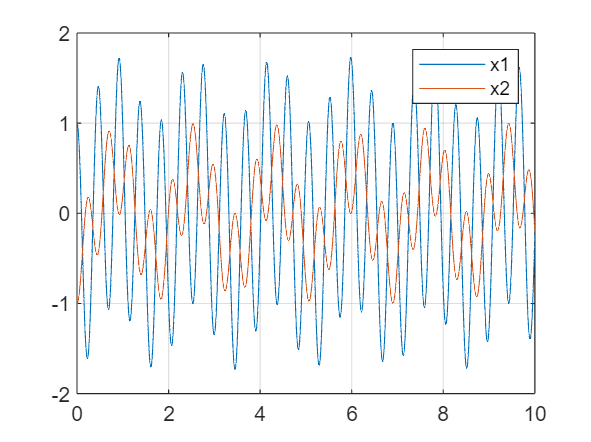

plot(tspan, x3)
hold on
plot(tspan, x4)
grid on
legend('x1', 'x2')
hold off